**EE-414 Speech Processing Lab**

**Lab-6**

**AIM**

- To understand the need for short term processing of speech.

- To compute short term energy and study its significance.

- To compute short term zero crossing rate and study its significance.

- To compute short term autocorrelation and study its significance.

**Theory :**

Speech is produced from a time varying vocal tract system with time varying excitation. As a result the speech signal is non-stationary in nature. Speech signal may be stationary when it is viewed in blocks  of 10-30 msec. Hence to process speech by different signal processing tools, it is viewed in terms of 10-30 msec. Such a processing is termed as Short Term Processing (STP). 

**A. Short term energy(STE) **

**Theory : **

The energy associated with speech is time varying in nature. Hence the interest for any automatic processing of speech is to know how the energy is varying with time and to be more specific, energy associated with short term region of speech.

The relation for finding the short term energy can be derived from the total energy relation defined in signal processing.The total energy of an energy signal is given by

In case of short term energy computation we consider speech in terms of 10-30 msec . Let the samples in a frame of  speech are given by ***"******n=0 to n=N-1"***, where ***" N "*** is the length of frame (samples), then for energy computation the  speech will be zero outside the frame length. Then for energy computation amplitude of the speech samples will be zero outside the  frame. Accordingly we can write above mentioned relation as

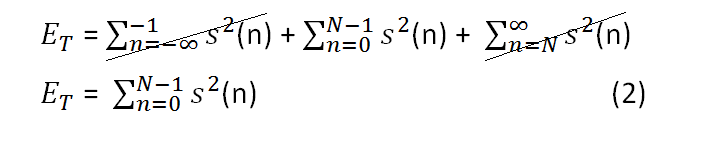

This relation will give total energy present in the frame of speech from ***" n=0 to n=N-1 "***. To represent more specifically, only one frame of speech we use the relation

 

where "***w(n)***" represent the windowing function of finite duration. There are several windowing functions present in the signal processing literature. The mostly used ones include rectangular, hanning and hamming. For all time domain parameters estimation we use the rectangular window  for its simplicity.

Now we can write the relation of short term energy as follows

 

where ***"n"*** is the shift / rate in number of samples at which we are interested in knowing the short term energy. The shift can be as small as one sample or as large as frame size. The short term energy computed for every sample shift may not be required since the energy variation in case of speech is relatively slow. For this reason the shift is kept much larger than one sample. Usually it is about half the frame size.

**PROCEDURE**

Record (16kHz, 16bit) the word “**speech signal**”; truncate long silence regions. 

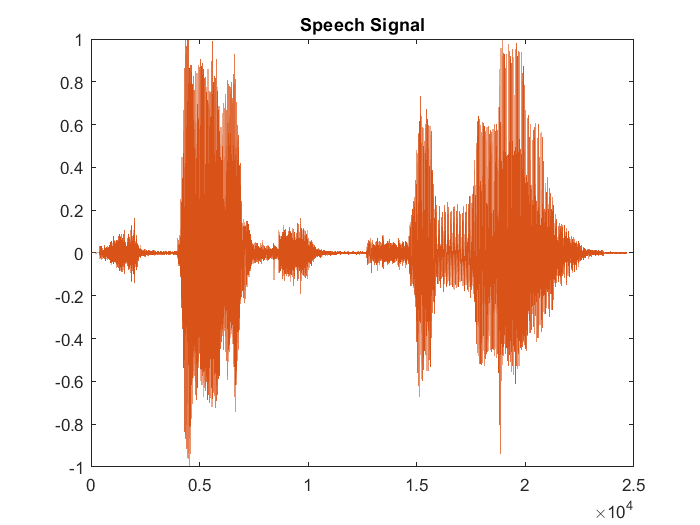

[y,Fs] = audioread('speech_signal.wav');
sound(y,Fs);
plot(y)
title('Speech Signal');

- Compute and plot STE (as a function of frame index) using frame size as 20ms and  frameshift as 10ms.

[STE] = short_term_energy(y,16000,20,10)

STE =     0.0000    0.0215    0.0412    0.0438    0.0903    0.1537    0.2207    0.3556    0.4836    0.4042    0.6203    0.9098    0.5315    0.1121    0.0210    0.0124    0.0077    0.0057    0.0042    0.0038    0.0037    0.0028    0.0023    0.0049    0.8922   19.7289   71.2932   96.3534   71.6616   49.0641   46.0542   50.3314   50.1744   49.9971   49.4096   42.9229   29.6037   21.1349   22.9808   24.8838   29.5337   29.8551   14.9539    3.9161    2.2321    0.6973    0.1619    0.1141    0.1103    0.0936


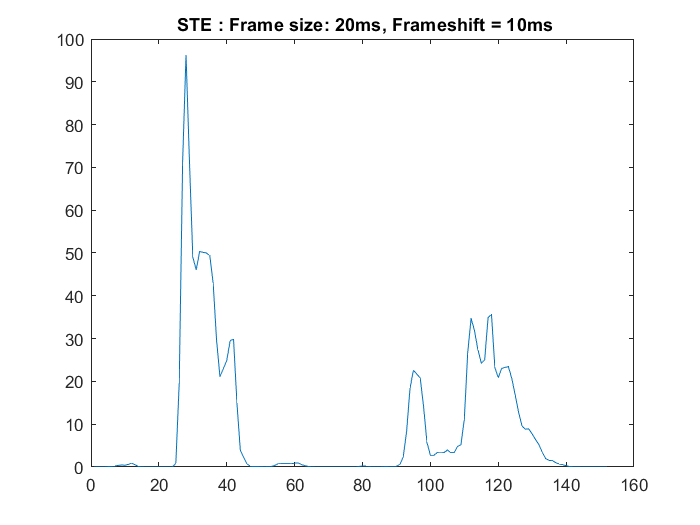

plot(STE);
title(' STE : Frame size: 20ms, Frameshift = 10ms');

2. Demonstrate and explain the effect of the window size on STE by taking window size of 20ms, 30ms, 50ms, 100ms. Also comment on which frame size is preferred.

[STE1] = short_term_energy(y,16000,20,10)

STE1 =     0.0000    0.0215    0.0412    0.0438    0.0903    0.1537    0.2207    0.3556    0.4836    0.4042    0.6203    0.9098    0.5315    0.1121    0.0210    0.0124    0.0077    0.0057    0.0042    0.0038    0.0037    0.0028    0.0023    0.0049    0.8922   19.7289   71.2932   96.3534   71.6616   49.0641   46.0542   50.3314   50.1744   49.9971   49.4096   42.9229   29.6037   21.1349   22.9808   24.8838   29.5337   29.8551   14.9539    3.9161    2.2321    0.6973    0.1619    0.1141    0.1103    0.0936


[STE2] = short_term_energy(y,16000,30,10)

STE2 =     0.0215    0.0412    0.0654    0.1100    0.1779    0.2868    0.4432    0.6167    0.6267    0.8814    1.0529    1.0088    0.5447    0.1199    0.0255    0.0155    0.0103    0.0074    0.0064    0.0053    0.0050    0.0038    0.0062    0.8933   19.7327   72.1816  115.1939  124.1143   92.9648   73.8151   71.6346   74.9254   75.5775   74.0036   68.3261   53.6102   40.0514   33.6681   35.3314   42.0668   42.2057   32.1369   16.5881    4.5139    2.3316    0.7597    0.2136    0.1727    0.1453    0.1182


[STE3] = short_term_energy(y,16000,50,10)

STE3 =     0.0654    0.1315    0.2191    0.3306    0.5335    0.7705    0.8474    1.2370    1.5365    1.4129    1.1650    1.0297    0.5571    0.1276    0.0313    0.0197    0.0141    0.0111    0.0092    0.0077    0.0099    0.8960   19.7350   72.1865  116.0861  143.8432  164.2580  170.1685  143.2962  123.9895  121.6317  124.3350  118.5005  103.6073   89.4610   76.5910   64.9351   63.2017   65.1865   57.0207   46.1218   34.3690   17.2855    4.6758    2.4457    0.8700    0.3072    0.2323    0.2363    0.2114


[STE4] = short_term_energy(y,16000,100,10)

STE4 =     0.8358    0.9789    1.4561    1.8672    1.9464    1.9354    1.8771    1.7941    1.6641    1.4442    1.1847    1.0438    0.5681    0.1368    0.0389    0.0296    0.9102   19.7461   72.1957  116.0938  143.8530  165.1540  189.9035  215.4827  240.0756  265.4749  288.5930  288.6690  246.9035  213.4505  198.2227  189.2702  181.7022  168.7938  146.4817  122.7128   99.3041   80.4872   69.8623   59.4663   46.9918   34.6762   17.5178    4.9121    2.6571    1.2849    1.1275    1.3831    1.7506    2.0652


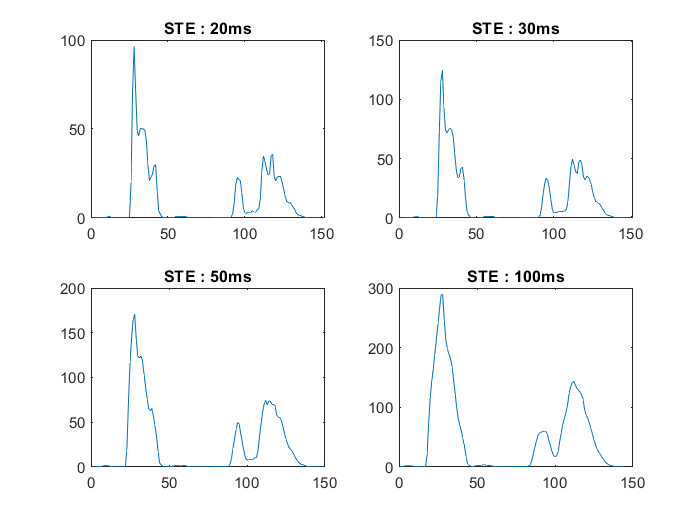


figure();
subplot(2,2,1);
plot(STE1);
title('STE : 20ms');
subplot(2,2,2);
plot(STE2);
title('STE : 30ms');
subplot(2,2,3);
plot(STE3);
title('STE : 50ms');
subplot(2,2,4);
plot(STE4);
title('STE : 100ms');

**OBSERVATIONS AND COMMENTS:**

**1) **STE is higher for voiced sounds and lower for unvoiced. Hence, for initial "s" has negligible energy and the voiced vowel"ee" has high STE.

**2)  **As we are moving from 20ms to 100ms window, some einformation is getting lost. Extra valley like structures, as seen in 20ms and 30ms are not seen in 50 ms and 100 ms window.

3) This happens because quasi-stationarity assumption, holds true between 10-30 ms approx and does not hold true for higher window lengths.

4) Hence, I think 20 ms frame size is preferred as information is retained.

**B. Short term Zero Crossing Rate(ST-ZCR) : **

Zero Crossing Rate gives information about the number of zero-crossings present in a given signal. Intuitively, if the number of zero crossings are more in a given signal, then the signal is changing rapidly and accordingly the signal may contain  high frequency information. Thus ZCR gives an indirect information about the frequency content of the signal.

This relation can be modified for non-stationary signals like speech and termed as short term ZCR. It is defined as

The factor "2" comes in the denominator to take care of the fact that there will be two zero crossings per cycle of one signal

In case of speech the nature of signal changes with time over few msec. For instance, from initial voiced to unvoiced and back to voiced and so on. To have some useful information,  ZCR needs to be computed using typical frame size of 10-30 msec with half the frame size as shift. 

- Compute and plot ST-ZCR for speech signal using frame size as 20ms and  frameshift as 10ms.

[ZCR] = zero_crossing_rate(y,16000,20,10)

ZCR =     0.0031    0.0453    0.1453    0.2750    0.3641    0.3672    0.3563    0.3547    0.3953    0.4094    0.4016    0.4078    0.3641    0.3359    0.3359    0.3375    0.3281    0.3234    0.2859    0.2422    0.2250    0.2203    0.1906    0.1281    0.0953    0.0641    0.0422    0.0547    0.0672    0.0734    0.0781    0.0719    0.0656    0.0766    0.0891    0.1047    0.1344    0.1609    0.1609    0.1359    0.1219    0.0953    0.0578    0.0406    0.0391    0.1062    0.1484    0.1328    0.1422    0.1328


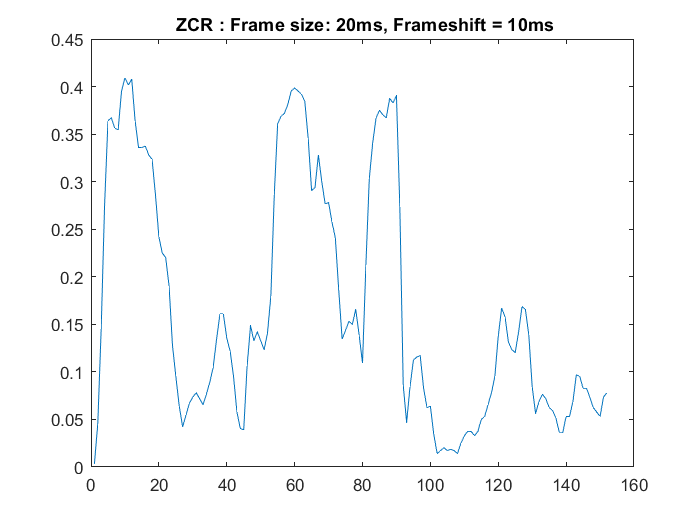

figure();
plot(ZCR);
title(' ZCR : Frame size: 20ms, Frameshift = 10ms');

        2. Demonstrate and explain the effect of the window on ST-ZCR by taking window size of 20ms, 30ms, 50ms, 100ms. Also comment on which frame size is preferred.

[ZCR1] = zero_crossing_rate(y,16000,20,10)

ZCR1 =     0.0031    0.0453    0.1453    0.2750    0.3641    0.3672    0.3563    0.3547    0.3953    0.4094    0.4016    0.4078    0.3641    0.3359    0.3359    0.3375    0.3281    0.3234    0.2859    0.2422    0.2250    0.2203    0.1906    0.1281    0.0953    0.0641    0.0422    0.0547    0.0672    0.0734    0.0781    0.0719    0.0656    0.0766    0.0891    0.1047    0.1344    0.1609    0.1609    0.1359    0.1219    0.0953    0.0578    0.0406    0.0391    0.1062    0.1484    0.1328    0.1422    0.1328


[ZCR2] = zero_crossing_rate(y,16000,30,10)

ZCR2 =     0.0313    0.0979    0.2125    0.3115    0.3604    0.3646    0.3542    0.3844    0.3896    0.4156    0.3979    0.3854    0.3531    0.3385    0.3344    0.3344    0.3260    0.3000    0.2677    0.2344    0.2240    0.2000    0.1594    0.1167    0.0760    0.0583    0.0490    0.0604    0.0698    0.0760    0.0729    0.0708    0.0719    0.0833    0.0969    0.1219    0.1448    0.1604    0.1448    0.1344    0.1010    0.0823    0.0469    0.0448    0.0792    0.1167    0.1427    0.1396    0.1323    0.1333


[ZCR3] = zero_crossing_rate(y,16000,50,10)

ZCR3 =     0.1288    0.2050    0.2750    0.3294    0.3581    0.3775    0.3769    0.3919    0.3975    0.3956    0.3731    0.3663    0.3469    0.3350    0.3306    0.3156    0.2925    0.2700    0.2487    0.2169    0.1856    0.1581    0.1219    0.0869    0.0675    0.0619    0.0587    0.0675    0.0706    0.0719    0.0744    0.0788    0.0850    0.1037    0.1225    0.1381    0.1412    0.1450    0.1250    0.1037    0.0769    0.0650    0.0706    0.0862    0.1013    0.1269    0.1388    0.1331    0.1356    0.1525


[ZCR4] = zero_crossing_rate(y,16000,100,10)

ZCR4 =     0.2534    0.2909    0.3334    0.3638    0.3772    0.3756    0.3719    0.3697    0.3663    0.3634    0.3444    0.3297    0.3088    0.2922    0.2737    0.2506    0.2253    0.1959    0.1678    0.1422    0.1241    0.1084    0.0947    0.0788    0.0697    0.0681    0.0688    0.0762    0.0872    0.0975    0.1062    0.1100    0.1150    0.1147    0.1131    0.1075    0.1031    0.1078    0.1056    0.1025    0.1019    0.1019    0.1022    0.1109    0.1269    0.1600    0.1913    0.2125    0.2362    0.2622


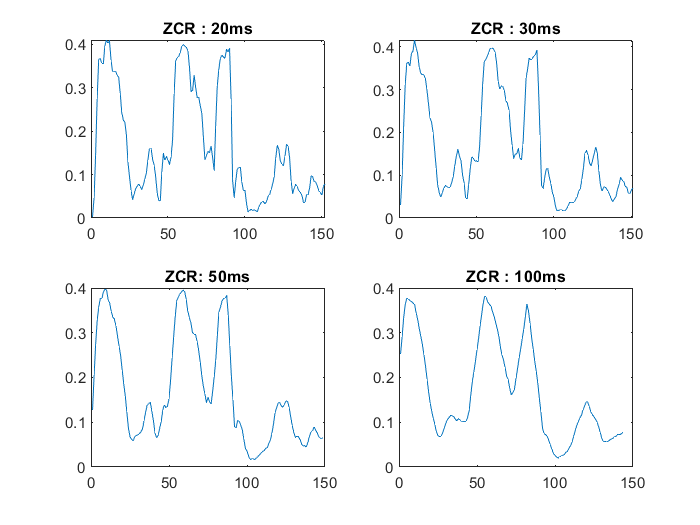



figure();
subplot(2,2,1);
plot(ZCR1);
title('ZCR : 20ms');
subplot(2,2,2);
plot(ZCR2);
title('ZCR : 30ms');
subplot(2,2,3);
plot(ZCR3);
title('ZCR: 50ms');
subplot(2,2,4);
plot(ZCR4);
title('ZCR : 100ms');

**Observations and Comments:**

1) As it can be observed, in case of unvoiced sounds like |s|, the ZCR value is significantly high compared to the region of voiced sounds like `ee` and hence can be used for distinguishing voiced and unvoiced regions.

2) I prefer 20 ms as the frame size as it is apt size: not very long and not very small. The quasi-statinarity assumptions also hold valid at 20ms. 

3) As it can be observed above, more information  can be learned from 20ms frame shift.

**C. Short term Autocorrelation**

Do each of the following for one speech frame at the centre of the vowel, and another speech frame at the centre of  the consonant “s”.

fs = 16000

fs = 16000

%----Vowel : ee-----%
t1=0.288*fs : 0.414*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);

%----Consonant : s-----%
t2=0.039*fs : 0.140*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y(t2);

- Compute and plot short term Autocorrelation function (as a function of delay index) for a 20ms long speech frame.

acf1 = autocorrelation(x1,16000,20)

acf1 =    53.1716   43.0700   30.2049   31.4946   39.4477   38.5109   28.4416   21.6623   19.3332   15.9844   11.0974    7.4349    3.9220   -3.3905  -11.3397  -15.3035  -16.1616  -18.2855  -24.2057  -30.4788  -33.8504  -34.2330  -33.5948  -34.3027  -36.8751  -39.5892  -39.1860  -35.3075  -31.6491  -30.2703  -29.7693  -28.0525  -23.9563  -18.2393  -12.5533   -8.7084   -7.0133   -4.4385    1.6224    9.4270   14.4779   15.8149   16.9595   20.5636   26.4832   31.4226   32.8451   31.4343   30.5098   32.8688


acf2 = autocorrelation(x2,16000,20)

acf2 =     3.1672   -2.1452    0.9716    0.3020   -0.6093    0.6661   -0.4625    0.3042   -0.1526    0.2543   -0.5166    0.8328   -0.7901    0.5371   -0.1196   -0.0773    0.1432   -0.0556   -0.0223    0.0354    0.0276   -0.2943    0.4933   -0.7424    0.6400   -0.3906    0.0478    0.0059    0.0407   -0.0136   -0.2027    0.4200   -0.5908    0.6285   -0.7364    0.5323   -0.3098   -0.1545    0.2596   -0.3766    0.0975   -0.1208    0.0175   -0.1967    0.3158   -0.4255    0.2913   -0.0988   -0.1533    0.2256


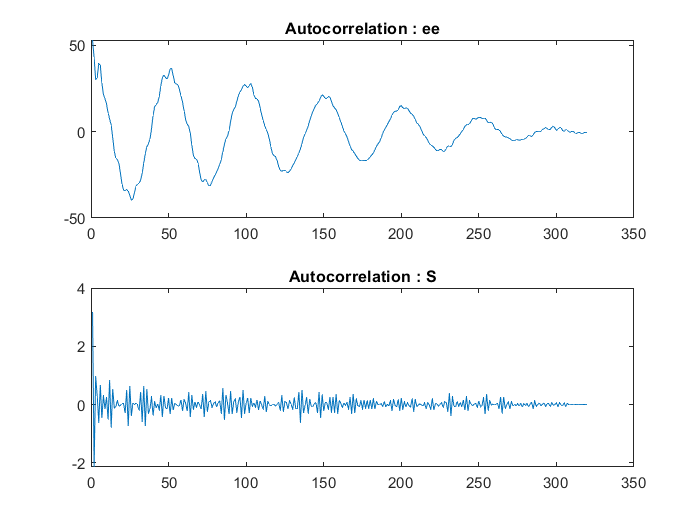

figure();
subplot(2,1,1)
plot(acf1)
title('Autocorrelation : ee');
subplot(2,1,2)
plot(acf2)
title('Autocorrelation : S');

2. Demonstrate and explain the effect of the window on Short term Autocorrelation by taking window size of 10ms, 20ms, 50ms, 100ms. Also comment on which frame size is preferred.

acf1 = autocorrelation(x1,16000,10)

acf1 =    30.3545   25.4927   19.0521   19.4457   23.3282   22.4568   16.3521   12.0898   11.5536   10.5087    6.7516    2.8718    0.6234   -1.7777   -5.2934   -8.6409  -10.5660  -11.8076  -14.0631  -16.8872  -18.9932  -19.6905  -19.4288  -19.6503  -20.7175  -21.5390  -20.7369  -18.7020  -17.1709  -16.5869  -15.6600  -13.5374  -10.7253   -8.4866   -6.7170   -4.2920   -1.6734    0.3497    2.1947    5.0825    8.3318    9.6250    9.5159   11.1827   15.1496   17.2667   15.5448   14.1519   16.2647   18.9911


acf2 = autocorrelation(x2,16000,10)

acf2 =     0.9181   -0.5176    0.3287    0.0995   -0.0995    0.2359   -0.1648    0.1435   -0.0278    0.0346   -0.0788    0.2043   -0.1835    0.1756   -0.0890    0.1451   -0.1416    0.1106   -0.0242   -0.0649    0.1263   -0.2469    0.2628   -0.2725    0.1364   -0.0797    0.0232   -0.0836    0.0659   -0.0272   -0.1199    0.1489   -0.1848    0.1144   -0.1512    0.0315   -0.0599   -0.0299   -0.1344    0.1149   -0.2340    0.0675   -0.0498   -0.1224    0.1243   -0.2242    0.1515   -0.1588    0.0571   -0.0925


figure();
subplot(4,2,1)
plot(acf1)
title('Autocorrelation : ee : 10ms ');
subplot(4,2,2)
plot(acf2)
title('Autocorrelation : S : 10ms');
acf1 = autocorrelation(x1,16000,20)

acf1 =    53.1716   43.0700   30.2049   31.4946   39.4477   38.5109   28.4416   21.6623   19.3332   15.9844   11.0974    7.4349    3.9220   -3.3905  -11.3397  -15.3035  -16.1616  -18.2855  -24.2057  -30.4788  -33.8504  -34.2330  -33.5948  -34.3027  -36.8751  -39.5892  -39.1860  -35.3075  -31.6491  -30.2703  -29.7693  -28.0525  -23.9563  -18.2393  -12.5533   -8.7084   -7.0133   -4.4385    1.6224    9.4270   14.4779   15.8149   16.9595   20.5636   26.4832   31.4226   32.8451   31.4343   30.5098   32.8688


acf2 = autocorrelation(x2,16000,20)

acf2 =     3.1672   -2.1452    0.9716    0.3020   -0.6093    0.6661   -0.4625    0.3042   -0.1526    0.2543   -0.5166    0.8328   -0.7901    0.5371   -0.1196   -0.0773    0.1432   -0.0556   -0.0223    0.0354    0.0276   -0.2943    0.4933   -0.7424    0.6400   -0.3906    0.0478    0.0059    0.0407   -0.0136   -0.2027    0.4200   -0.5908    0.6285   -0.7364    0.5323   -0.3098   -0.1545    0.2596   -0.3766    0.0975   -0.1208    0.0175   -0.1967    0.3158   -0.4255    0.2913   -0.0988   -0.1533    0.2256


subplot(4,2,3)
plot(acf1)
title('Autocorrelation : ee : 20ms');
subplot(4,2,4)
plot(acf2)
title('Autocorrelation : S: 20ms');
acf1 = autocorrelation(x1,16000,50)

acf1 =   129.7558   95.4804   53.7875   66.1160   97.1663   88.7246   55.9087   48.3891   52.1967   37.4066   18.3890   18.7367   20.7566   -1.4908  -28.4829  -34.0492  -28.2355  -34.3790  -51.1429  -63.2361  -71.0549  -77.1409  -76.6920  -71.2187  -74.3601  -89.3325  -96.1876  -83.7115  -67.9809  -67.1537  -73.7436  -71.8930  -60.9693  -49.1400  -37.3421  -24.9677  -21.5640  -24.2245  -12.8348   14.6525   31.0601   24.8271   24.1693   43.6919   59.9519   58.3246   62.4631   82.5079   84.7559   65.1531


acf2 = autocorrelation(x2,16000,50)

acf2 =    20.3130  -15.0544    8.5761    0.6279   -5.0943    8.2175   -7.5498    6.3976   -3.4872    1.7932   -0.2666    0.6926   -0.3618    0.4862    0.2426    0.2200   -1.1269    2.2957   -3.3023    2.7148   -1.8727   -1.2322    3.6024   -6.7881    6.9965   -6.4152    2.6720    0.0320   -3.7214    4.5281   -5.2828    3.5406   -2.9937    1.1847   -1.1773   -0.5745    1.1232   -3.0495    2.6250   -2.4770    0.1248    1.3054   -3.2888    3.4083   -2.4758    0.1609    2.2104   -4.0170    4.7002   -3.9323


subplot(4,2,5)
plot(acf1)
title('Autocorrelation : ee : 50ms');
subplot(4,2,6)
plot(acf2)
title('Autocorrelation : S: 50ms');
acf1 = autocorrelation(x1,16000,100)

acf1 =   222.7109  148.2198   55.9795   80.8374  150.1767  145.5471   90.5228   67.4513   59.8880   41.9537   35.6110   43.8619   28.8540  -18.8281  -52.8318  -51.8922  -38.5111  -41.4918  -72.9739 -111.2839 -124.2231 -107.4442  -93.6434 -103.6790 -126.0763 -144.2472 -141.3864 -115.4659  -91.0619  -96.1952 -119.3033 -119.6068  -87.4783  -53.1179  -40.0288  -43.9709  -50.6882  -38.8257    4.0217   44.7260   42.4635   21.0491   35.5319   80.3841  104.3275   96.5713   95.8129  113.5779  119.7212  113.6105


acf2 = autocorrelation(x2,16000,100)

acf2 =    74.8124  -59.4251   32.8963   -0.7296  -18.4774   27.6701  -24.3664   17.9503   -9.2818    5.7514   -5.4586    9.2766   -9.8964    7.5842   -2.0251   -0.6825   -0.5941    4.7879  -10.1136   11.9920  -12.0862    6.4560    0.8889  -12.3476   19.8312  -24.1367   18.8351  -11.6392    0.4682    5.6243  -10.4628    8.5392   -6.7746    1.9540   -2.4559    2.8903   -6.9137    6.2198   -4.3947   -2.4752    7.4525  -11.5047   10.1809   -6.4278    0.5749    3.7731   -4.7132    1.4342    4.7132   -9.2670


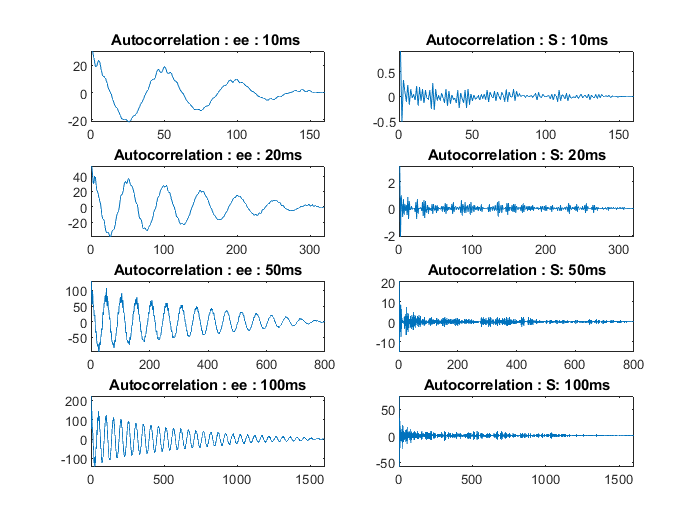

subplot(4,2,7)
plot(acf1)
title('Autocorrelation : ee : 100ms');
subplot(4,2,8)
plot(acf2)
title('Autocorrelation : S: 100ms');

**Observations:**

**1) Autocorrelation of vowels" ee" is periodic in nature, whereas of unvoiced consonants like "S" is completly random.**

**2) On increasing the window length for periodic signals( voiced) more periods are observed. This is not appropiate for for precise measurement of pitch period. Thus, 20 ms frame size is prefrred.**

**3) WIndow size doen't matter much for unvoiced consonants such as "S".**

3. Demonstrate and explain the effect of the window shape on Short term Autocorrelation by taking the ‘rectangular’, ‘Hamming’ and ‘Hanning’ window. Take frame size as the most preferred frame size computed in (b). Also comment on which window is preferred.

% For window size 20ms
fs = 16000

fs = 16000

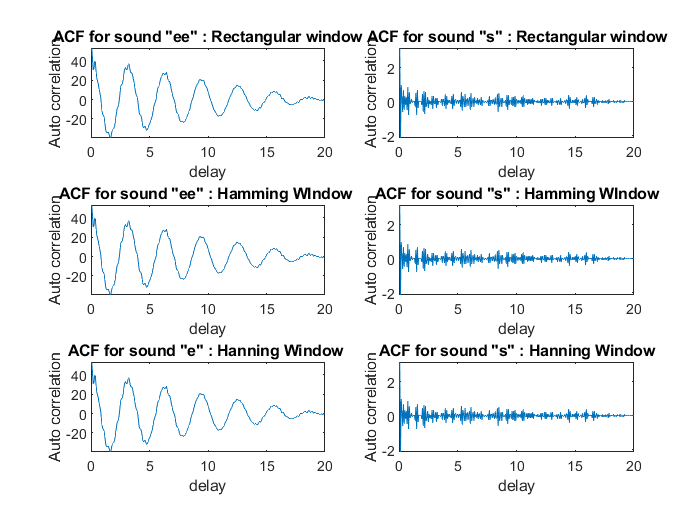

% Rectangular window
Frame_size=20;
ye_a=autocorrelation(x1,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_a)/fs))*1000;
figure();
subplot(3,2,1)
plot(te_a,ye_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "ee" : Rectangular window');

Frame_size=20;
ye_a=autocorrelation(x2,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_a)/fs))*1000;
subplot(3,2,2)
plot(te_a,ye_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "s" : Rectangular window');
%--------------------------------------------------------%
% Hamming window
Frame_size=20;
window_length=Frame_size*fs;
win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x1);
ye_hamm_a=autocorrelation(y_e_hamm,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_hamm_a)/fs))*1000;
subplot(3,2,3)
plot(te_a,ye_hamm_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "ee" : Hamming WIndow ');

Frame_size=20;
window_length=Frame_size*fs;
win_hamm = dsp.Window('Hamming');
y_e_hamm = win_hamm(x2);
ye_hamm_a=autocorrelation(y_e_hamm,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_hamm_a)/fs))*1000;
subplot(3,2,4)
plot(te_a,ye_hamm_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "s" : Hamming WIndow');

%-----------------------------------------------------------%

% Hanning window
Frame_size=20;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x1);
ye_hann_a=autocorrelation(y_e_hann,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_hann_a)/fs))*1000;
subplot(3,2,5)
plot(te_a,ye_hann_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "e" : Hanning Window ');

Frame_size=20;
window_length=Frame_size*fs;
win_hann = dsp.Window('Hanning');
y_e_hann = win_hann(x2);
ye_hann_a=autocorrelation(y_e_hann,fs,Frame_size);
te_a=(1/fs:1/fs:(length(ye_hann_a)/fs))*1000;
subplot(3,2,6)
plot(te_a,ye_hann_a);
xlabel('delay');
ylabel('Auto correlation');
title('ACF for sound "s" : Hanning Window');

**Comments and observations:**

**1) **In hamming and hanning window the ends of frames are supressed. 

2) Both Hamming and Hanning window approximately similar structures are observed. Hanning window surpasses the ends more as compared to Hamming.

3) SInce, we are more interested in "First major peak" in the autocorrelation plot, for most of the applications, Hamming or Hanning windows are preferred more over rectangular window.

function[e]=short_term_energy(speechsignal,fs,Frame_size,Frame_shift)
y=speechsignal;
Frame_size= Frame_size/1000;
Frame_shift= Frame_shift/1000 ;
window_length=Frame_size*fs;
sample_shift=Frame_shift*fs;
sum=0 ;energy=0 ;
w=rectwin(window_length);
jj=1 ;

for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
    for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+window_length)
        y(j)=y(j)*w(jj) ;
        jj=jj+1 ;
        yy=y(j)*y(j);
        sum=sum+yy;
    end
    energy(i)=sum ;
    sum=0 ; jj=1 ;
end
w=0;
e=energy;
return ;
end

function[z]=zero_crossing_rate(speechsignal,fs,Frame_size,Frame_shift)
y=speechsignal;
Frame_size= Frame_size/1000;
Frame_shift= Frame_shift/1000 ;
window_length=Frame_size*fs;
sample_shift=Frame_shift*fs;
sum=0 ;energy=0 ;
w=rectwin(window_length);
jj=1 ;

for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
    y(((i-1)*sample_shift)+1)=y(((i-1)*sample_shift)+1)*w(jj);
    jj=jj+1 ;
    for j=(((i-1)*sample_shift)+2):(((i-1)*sample_shift)+window_length)
        y(j)=y(j)*w(jj) ; jj=jj+1 ;
        yy=y(j)*y(j-1);
        if(yy<0)
            sum=sum+1;
        end
    end
    zcr(i)=sum/(2*window_length);
    sum=0 ; jj=1 ;
end
w=0;
z=zcr;
return ;
end

function [a]=autocorrelation(speechsignal,fs,Frame_size)
y=speechsignal;
Frame_size= Frame_size/1000;
window_length=Frame_size*fs;
max_value=max(abs(y));
y=y/max_value;
y=y(1:window_length);
sum=0;
autocorrelatio=[];
for l=0: (length(y)-1)
    sum=0;
    for u=1:length(y)-l
        s=y(u)*y(u+l);
        sum=sum+s;
    end
    autocorrelatio(l+1)=sum;
end
a=autocorrelatio;
end


